# Week 6 Help – Arrays

clear; clc

## Array Creation

### Array Vocab

To be clear on the vocabulary, lets differentiate between vectors, matrices, and arrays by the following:

- Vector: One-dimensional arrays (Example: `[0, 1, 2, 3]`)

- Matrix: Two-dimensional arrays (Example: `[0, 1; 2, 3]`)

- Array: N-dimensional arrays

So a vector is an array, but an array is not a vector. Likewise a matrix is an array, but an array is not a matrix. Vectors and matrices are **subsets** of arrays.

### Array Orientation

From linear algebra, vectors can either be column vectors or row vectors, we can denote this in Matlab as well

r = [0, 1, 2, 3] % This is a row vector since it is values separated by ","

r =      0     1     2     3


c = [0; 1; 2; 3] % This is a column vectors since it uses ";"

c =      0
     1
     2
     3


We can also denote array tranposes with the `'` symbol.

c = [0, 1, 2, 3]' % Outputs column vector since we tranposed a row vector

c =      0
     1
     2
     3


**Note:** The `'` symbol technically means a complex conjugate and note an array tranpose. The latter is truely denoted by a `.'` instead. To show the difference we can try with an array of complex numbers.

iV = [1.0 + 1.5i, 0.3 - 0.5i]

iV =    1.0000 + 1.5000i   0.3000 - 0.5000i


iV'

ans =    1.0000 - 1.5000i
   0.3000 + 0.5000i


iV.'

ans =    1.0000 + 1.5000i
   0.3000 - 0.5000i


They are **not the same**, so by default, it is best practice to use `.'` wherever possible.

### Linearly Spaced Arrays

For arrays of fixed length or fixed step size, we can use built in Matlab functions to create them. Useful for setting fixed time steps of a simulation to test, or build plots of varying detail.

% User Inputs
x0 = 0; % Value of first index
xf = 10; % Value of final index
dx = 0.1; % Step between indexs for fixed step array
N  = 50;    % Number of total elements for fixed length array

% Creating Arrays
xFS = x0:dx:xf            % Fixed-step array

xFS =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


xFL = linspace(x0, xf, N) % Fixed-length array

xFL =          0    0.2041    0.4082    0.6122    0.8163    1.0204    1.2245    1.4286    1.6327    1.8367    2.0408    2.2449    2.4490    2.6531    2.8571    3.0612    3.2653    3.4694    3.6735    3.8776    4.0816    4.2857    4.4898    4.6939    4.8980    5.1020    5.3061    5.5102    5.7143    5.9184    6.1224    6.3265    6.5306    6.7347    6.9388    7.1429    7.3469    7.5510    7.7551    7.9592    8.1633    8.3673    8.5714    8.7755    8.9796    9.1837    9.3878    9.5918    9.7959   10.0000


fprintf("Fixed-step array length: %i | Fixed-length array step: %0.4f", length(xFS), diff(xFL(1:2)))

Fixed-step array length: 101 | Fixed-length array step: 0.2041

## Array Operations

### Parametric Arrays

Using already generated arrays, we can perform element-wise operations to build new arrays. We can try an example of this by plotting the [Butterfly Curve](https://en.wikipedia.org/wiki/Butterfly_curve_(transcendental)), which is a parametric equation in 2D. Other parametric equations can be found [here](https://elepa.files.wordpress.com/2013/11/fifty-famous-curves.pdf) as well.

% User Inputs
t0 = 0;
tf = 37.7;
N  = 500;

% Building time array
t = linspace(t0, tf, N)

t =          0    0.0756    0.1511    0.2267    0.3022    0.3778    0.4533    0.5289    0.6044    0.6800    0.7555    0.8311    0.9066    0.9822    1.0577    1.1333    1.2088    1.2844    1.3599    1.4355    1.5110    1.5866    1.6621    1.7377    1.8132    1.8888    1.9643    2.0399    2.1154    2.1910    2.2665    2.3421    2.4176    2.4932    2.5687    2.6443    2.7198    2.7954    2.8709    2.9465    3.0220    3.0976    3.1731    3.2487    3.3242    3.3998    3.4754    3.5509    3.6265    3.7020



% Creating Butterfly Curve
x = sin(t).*( exp(cos(t)) - 2*cos(4*t) - sin(t/12).^5 );

x =          0    0.0605    0.1568    0.3184    0.5624    0.8903    1.2864    1.7192    2.1454    2.5157    2.7814    2.9021    2.8518    2.6233    2.2304    1.7068    1.1033    0.4812   -0.0947   -0.5645   -0.8800   -1.0116   -0.9513   -0.7138   -0.3345    0.1354    0.6355    1.1041    1.4861    1.7398    1.8417    1.7887    1.5978    1.3029    0.9490    0.5855    0.2591    0.0067   -0.1490   -0.2030   -0.1677   -0.0705    0.0510    0.1551    0.2029    0.1650    0.0263   -0.2110   -0.5272   -0.8873


y = cos(t).*( exp(cos(t)) - 2*cos(4*t) - sin(t/12).^5 );

y =     0.7183    0.7989    1.0299    1.3806    1.8040    2.2436    2.6406    2.9419    3.1065    3.1112    2.9528    2.6485    2.2325    1.7513    1.2566    0.7984    0.4178    0.1417   -0.0203   -0.0769   -0.0527    0.0160    0.0871    0.1202    0.0827   -0.0446   -0.2638   -0.5596   -0.9002   -1.2426   -1.5378   -1.7389   -1.8073   -1.7196   -1.4713   -1.0787   -0.5774   -0.0187    0.5370    1.0273    1.3961    1.6004    1.6164    1.4423    1.0984    0.6248    0.0759   -0.4864   -1.0008   -1.4140


Some functions take arrays and output arrays by default like `sin` and `cos`, while others need to add a period before to denote the operation is element-wise specifically like `.*`, `./`, or `.^`. The exception to these cases is when multiplying or dividing by a scalar like above with `2*cos(4*t)` even when `t` is an array. We can visualize this by plotting:

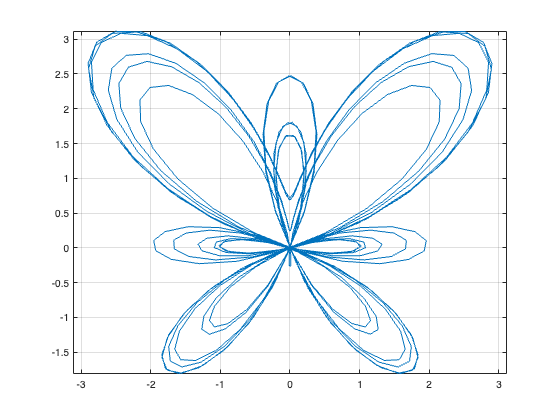

plot(x, y)
axis equal
grid on

### Concatenate Arrays

We can combine arrays into larger arrays wherever convenient to avoid poluting the namespace of our Matlab session. We can try that using the parametric arrays created for the Butterfly Curve

% Concatenating arrays vertically creates 2xN array
X = [x; y]

X =          0    0.0605    0.1568    0.3184    0.5624    0.8903    1.2864    1.7192    2.1454    2.5157    2.7814    2.9021    2.8518    2.6233    2.2304    1.7068    1.1033    0.4812   -0.0947   -0.5645   -0.8800   -1.0116   -0.9513   -0.7138   -0.3345    0.1354    0.6355    1.1041    1.4861    1.7398    1.8417    1.7887    1.5978    1.3029    0.9490    0.5855    0.2591    0.0067   -0.1490   -0.2030   -0.1677   -0.0705    0.0510    0.1551    0.2029    0.1650    0.0263   -0.2110   -0.5272   -0.8873
    0.7183    0.7989    1.0299    1.3806    1.8040    2.2436    2.6406    2.9419    3.1065    3.1112    2.9528    2.6485    2.2325    1.7513    1.2566    0.7984    0.4178    0.1417   -0.0203   -0.0769   -0.0527    0.0160    0.0871    0.1202    0.0827   -0.0446   -0.2638   -0.5596   -0.9002   -1.2426   -1.5378   -1.7389   -1.8073   -1.7196   -1.4713   -1.0787   -0.5774   -0.0187    0.5370    1.0273    1.3961    1.6004    1.6164    1.4423    1.0984    0.6248    0.0759   -0.4864   -1.0008   -1


% Concatenating horizontally without transposing arrays creates 1x2N
Y = [x, y]

Y =          0    0.0605    0.1568    0.3184    0.5624    0.8903    1.2864    1.7192    2.1454    2.5157    2.7814    2.9021    2.8518    2.6233    2.2304    1.7068    1.1033    0.4812   -0.0947   -0.5645   -0.8800   -1.0116   -0.9513   -0.7138   -0.3345    0.1354    0.6355    1.1041    1.4861    1.7398    1.8417    1.7887    1.5978    1.3029    0.9490    0.5855    0.2591    0.0067   -0.1490   -0.2030   -0.1677   -0.0705    0.0510    0.1551    0.2029    0.1650    0.0263   -0.2110   -0.5272   -0.8873



% Now transposing creates Nx2 "table" of values
Z = [x.', y.']

Z =          0    0.7183
    0.0605    0.7989
    0.1568    1.0299
    0.3184    1.3806
    0.5624    1.8040
    0.8903    2.2436
    1.2864    2.6406
    1.7192    2.9419
    2.1454    3.1065
    2.5157    3.1112


For more information on concatenating arrays type `help cat` in the Command Window.

### Searching, Sorting, Flipping

% We can sort the array by smallest to largest and output its indexes with
[xsort, xidx] = sort(x);
xsort(1)     % Smallest value

ans = -2.9017

xsort(end)   % Largest value

ans = 2.9021

xsort(end-1) % Second largest value

ans = 2.8941


% We can sort by largest to smallest by flipping the array
xsort = flip(xsort);
xsort(1)   % Largest value

ans = 2.9021

xsort(end) % smallest value

ans = -2.9017

% or by doing instead sort(x, DIM, "descend")